Stationary Kalman Filter for Problem 4 (Empirical Model) calculated successfully.


Max eigenvalue of estimation error dynamics (A - Kpx*C): 0.9918


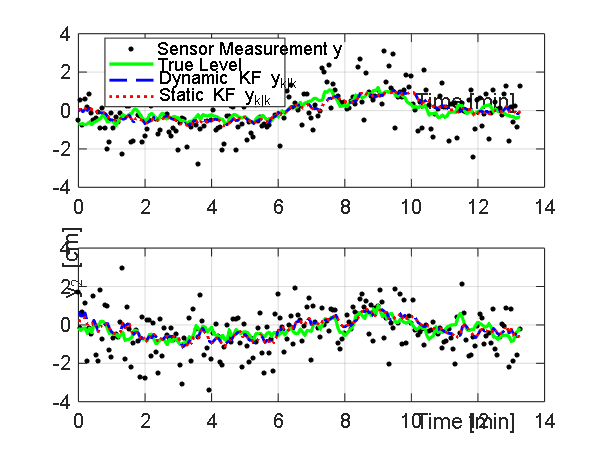

Stationary Kalman Filter for Problem 5 (Physical Brownian Model) calculated successfully.


Max eigenvalue of estimation error dynamics (A - Kpx*C): 0.8975


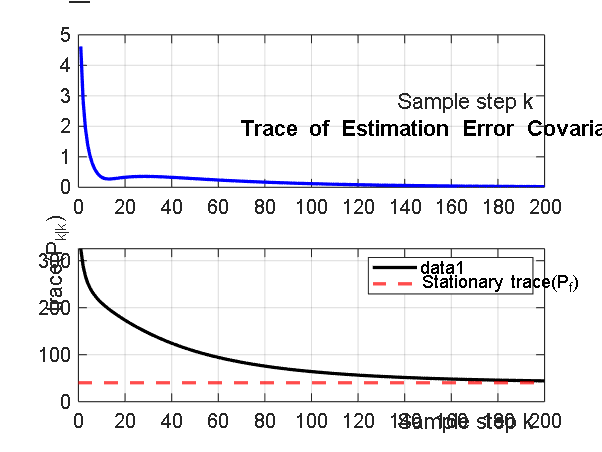

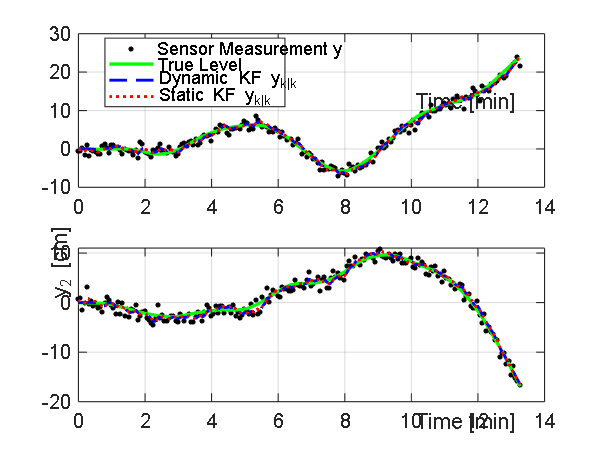

%% Problem 6.2: Design and Evaluation of Static and Dynamic Kalman Filters
%  Case: Stochastic disturbances WITHOUT step changes
%  Evaluation of both Problem 4 (Empirical) and Problem 5 (Physical) models

clear; clc; close all;

% Iterate over the two models to evaluate
for model_idx = 1:2
    
    if model_idx == 1
        % -----------------------------------------------------------------
        % MODEL 1: Empirical Identification (Problem 4)
        % -----------------------------------------------------------------
        model_name = 'Problem 4 (Empirical Model)';
        load('sysd_stochastic.mat');
        A = Ad_stochastic;
        B = Bd_stochastic;
        C = Cd_stochastic;
        D = Dd_stochastic;
        Ts = Ts_markov;
        
        G = B; % Assume noise enters through the actuators
        Q = diag([25^2, 25^2]); % Manual tuning
        
    else
        % -----------------------------------------------------------------
        % MODEL 2: Linearized Physical (Problem 5 - Brownian)
        % -----------------------------------------------------------------
        model_name = 'Problem 5 (Physical Brownian Model)';
        load('model_prob5_discrete.mat');
        A = A_d_Brownian;
        B = B_d_Brownian;
        C = C_d_Brownian;
        D = D_d_Brownian;
        Ts = Ts_disc;
        
        G = eye(size(A, 1)); % Covariance is already mapped for all states
        Q = Q_d_Brownian;    % Exact covariance from Van Loan's method
    end

    % ---------------------------------------------------------------------
    % Dimensions and Noise Specification
    % ---------------------------------------------------------------------
    nx = size(A, 1);
    nu = size(B, 2);
    ny = size(C, 1);
    nw = size(G, 2);
    
    R = (1.0^2) * eye(ny);  % Sensor variance (1 cm std)
    S = zeros(nw, ny);      
    
    x_bar0 = zeros(nx, 1);
    P0     = 100 * eye(nx);

    % ---------------------------------------------------------------------
    % Stationary Kalman Filter Design (DARE)
    % ---------------------------------------------------------------------
    P_stat   = dare(A', C', G*Q*G', R, G*S);
    Re_stat  = C * P_stat * C' + R;
    Kfx_stat = (P_stat * C') / Re_stat;
    Kfw_stat = S / Re_stat;
    Pf_stat  = P_stat - Kfx_stat * Re_stat * Kfx_stat';
    
    fprintf('\n======================================================\n');
    fprintf('Stationary Kalman Filter for %s calculated successfully.\n', model_name);
    fprintf('Max eigenvalue of estimation error dynamics (A - Kfx*C): %.4f\n', ...
        max(abs(eig(A - (A*Kfx_stat + G*Kfw_stat)*C))));
    fprintf('======================================================\n');

    % ---------------------------------------------------------------------
    % Stochastic Process Simulation (No step changes)
    % ---------------------------------------------------------------------
    rng(100);                    
    N_sim = 200;                 
    time_vec = (0:N_sim-1) * Ts;
    
    u = zeros(nu, N_sim); 
    
    L_q = chol(Q, 'lower');
    L_r = chol(R, 'lower');
    
    w = L_q * randn(nw, N_sim);   
    v = L_r * randn(ny, N_sim);   
    
    x_true = zeros(nx, N_sim);
    y_meas = zeros(ny, N_sim);
    
    x_true(:, 1) = x_bar0 + chol(P0, 'lower') * randn(nx, 1);
    
    for k = 1:N_sim-1
        y_meas(:, k)   = C * x_true(:, k) + D * u(:, k) + v(:, k);
        x_true(:, k+1) = A * x_true(:, k) + B * u(:, k) + G * w(:, k);
    end
    y_meas(:, N_sim) = C * x_true(:, N_sim) + D * u(:, N_sim) + v(:, N_sim);

    % ---------------------------------------------------------------------
    % Evaluation Loop (Dynamic vs Static)
    % ---------------------------------------------------------------------
    x_hat_dyn_filt  = zeros(nx, N_sim);
    x_hat_dyn_pred  = zeros(nx, N_sim);
    P_dyn_trace     = zeros(1, N_sim);
    gain_norm_diff  = zeros(1, N_sim);
    
    x_hat_stat_filt = zeros(nx, N_sim);
    x_hat_stat_pred = zeros(nx, N_sim);
    
    x_pred_dyn  = x_bar0;
    P_pred_dyn  = P0;
    x_pred_stat = x_bar0;
    
    for k = 1:N_sim
        % --- Dynamic Filter ---
        [x_f_dyn, P_f_dyn, x_p_dyn, P_p_dyn, ~, ~, Kfx_dyn] = ...
            kalman_filter_time_variant(y_meas(:, k), u(:, k), x_pred_dyn, P_pred_dyn, ...
                                       A, B, C, D, G, Q, R, S);
        
        x_hat_dyn_filt(:, k) = x_f_dyn;
        x_hat_dyn_pred(:, k) = x_pred_dyn;
        P_dyn_trace(k)       = trace(P_f_dyn);
        gain_norm_diff(k)    = norm(Kfx_dyn - Kfx_stat, 'fro');
        
        x_pred_dyn = x_p_dyn;
        P_pred_dyn = P_p_dyn;
        
        % --- Static Filter ---
        [x_f_stat, x_p_stat, ~] = ...
            kalman_filter_stationary(y_meas(:, k), u(:, k), x_pred_stat, ...
                                     A, B, C, D, G, Kfx_stat, Kfw_stat);
        
        x_hat_stat_filt(:, k) = x_f_stat;
        x_hat_stat_pred(:, k) = x_pred_stat;
        
        x_pred_stat = x_p_stat;
    end

    % ---------------------------------------------------------------------
    % Plotting and Analysis
    % ---------------------------------------------------------------------
    y_hat_dyn  = C * x_hat_dyn_filt  + D * u;
    y_hat_stat = C * x_hat_stat_filt + D * u;
    y_true     = C * x_true          + D * u;
    
    % Figure 1: Level Estimates
    figure('Name', sprintf('6.2 Level Estimates - %s', model_name), 'NumberTitle', 'off');
    for i = 1:ny
        subplot(ny, 1, i);
        plot(time_vec/60, y_meas(i, :), 'k.', 'MarkerSize', 7, 'DisplayName', 'Sensor Measurement y'); hold on;
        plot(time_vec/60, y_true(i, :), 'g-', 'LineWidth', 1.5, 'DisplayName', 'True Level');
        plot(time_vec/60, y_hat_dyn(i, :), 'b--', 'LineWidth', 1.3, 'DisplayName', 'Dynamic KF y_{k|k}');
        plot(time_vec/60, y_hat_stat(i, :), 'r:', 'LineWidth', 1.3, 'DisplayName', 'Static KF y_{k|k}');
        ylabel(sprintf('y_%d [cm]', i));
        xlabel('Time [min]');
        grid on;
        if i == 1
            legend('show', 'Interpreter', 'tex', 'Location', 'best');
            title(sprintf('Output Estimation: %s', model_name));
        end
    end
    
    % Figure 2: Gain and Covariance Convergence
    figure('Name', sprintf('6.2 Convergence - %s', model_name), 'NumberTitle', 'off');
    subplot(2, 1, 1);
    plot(1:N_sim, gain_norm_diff, 'b-', 'LineWidth', 1.5);
    ylabel('||K_{fx,k} - K_{fx}||_F');
    xlabel('Sample step k');
    title(sprintf('Filter Gain Convergence: %s', model_name));
    grid on;
    
    subplot(2, 1, 2);
    plot(1:N_sim, P_dyn_trace, 'k-', 'LineWidth', 1.5); hold on;
    yline(trace(Pf_stat), 'r--', 'LineWidth', 1.5, 'DisplayName', 'Stationary trace(P_f)');
    ylabel('trace(P_{k|k})');
    xlabel('Sample step k');
    title('Trace of Estimation Error Covariance P_{k|k}');
    legend('show');
    grid on;

end